## Okumura

Okumura 应用于移动通信系统，考虑了天线高度和地区覆盖类型，主要预测城市地区路径损耗，表示为：


$$PL_{OK}(d)[dB]=PL_F+A_{MU}(f,d)-G_{Rx}-G_{Tx}+G_{AREA}$$


其中$A_{MU}(f,d)$为频率f处的中等起伏衰减因子，$G_{Tx}$和$G_{Rx}$分别为发射和天线的增益，$G_{AREA}$是具体地区的传播环境增益。

## Hata

Hata将Okumura扩展至城市、郊区、开阔地，是当今最常用的路径损耗模型。在市区环境中Hata模型为：


$$PL_{Hata,U}(d)[dB]=69.55+26.16log_{10}{f_c}-13.82log_{10}h_{Tx}-C_{Rx}+(44.9-6.55log_{10}h_{Tx})log_{10}d$$


其中$C_{Rx}$是与接收天线相关的系数，对中等覆盖范围，取值为


$$C_{Rx}=0.8+(1.1log_{10}f_c-0.7)h_{Rx}-1.56log_{10}f_c$$


对郊区和开阔地，Hata模型分别为


$$PL_{Hata,SU}(d)[dB]=PL_{Hata,U}(d)-2(log_{10}(f_c/28))^2-5.4$$



$$PL_{Hata,O}(d)[dB]=PL_{Hata,U}(d)-4.78(log_{10}f_c)^2+18.33log_{10}f_c-40.97$$


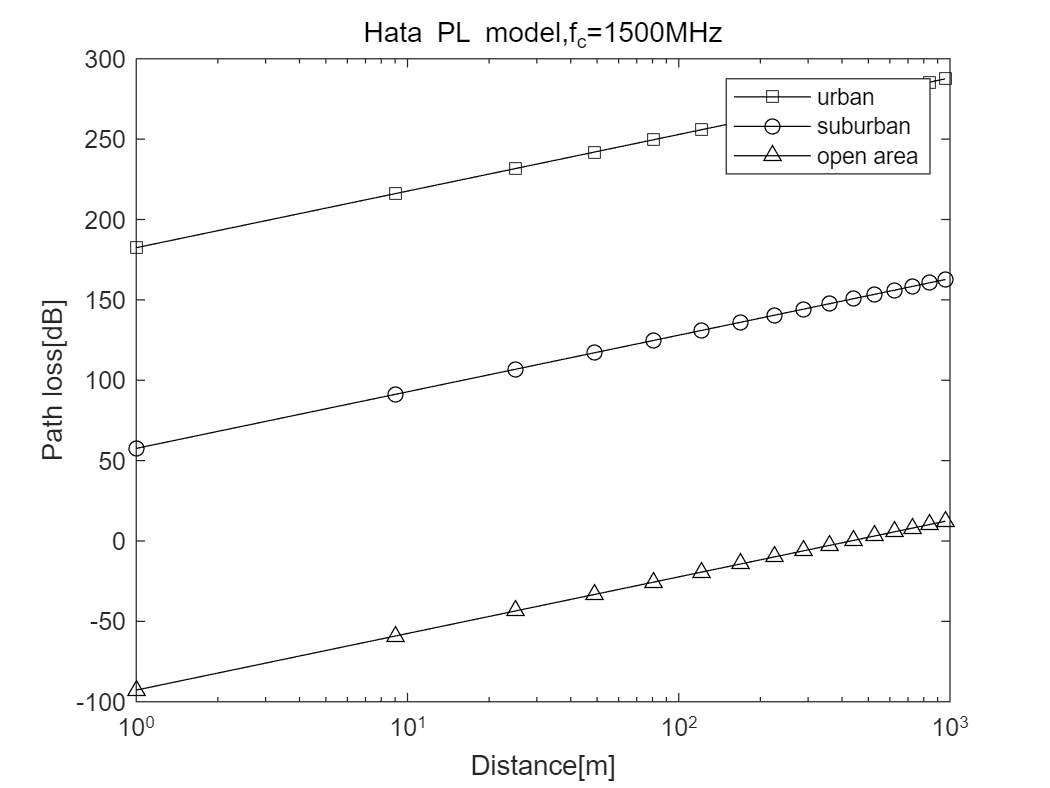

clear all;

fc = 1.5e9;
htx = 30;
hrx = 2;
distance = [1:2:31].^2;
y_urban = PL_Hata(fc,distance,htx,hrx,'urban');
y_suburban = PL_Hata(fc,distance,htx,hrx,'suburban');
y_open = PL_Hata(fc,distance,htx,hrx,'open');
semilogx(distance,y_urban,'k-s',distance,y_suburban,'k-o',distance,y_open,'k-^')
title(['Hata PL model,f_c=',num2str(fc/1e6),'MHz'])
xlabel('Distance[m]')
ylabel('Path loss[dB]')
legend('urban','suburban','open area')

function PL=PL_Hata(fc,d,htx,hrx,Etype)
    if nargin < 5
        Etype = 'URBAN';
    end
    if fc>=150e6 && fc<= 200e6
        C_Rx = 8.29*(log10(1.54*hrx))^2-1.1;
    elseif fc>200
        C_Rx = 3.2*(log10(11.75*hrx))^2-4.97;
    else 
        C_Rx = 0.8+(1.1*log10(fc)-0.7)*hrx-1.56*log10(fc);
    end

    PL = 69.55 + 26.16*log10(fc)-13.82*log10(htx)-C_Rx+(44.9-6.55*log10(htx))*log10(d/1000);
    Etype = upper(Etype);
    if(Etype(1)=='S')
        PL = PL-2*(log10(fc/28))^2-5.4;
    elseif(Etype(1)=='O')
        PL = PL + (18.33-4.78*log10(fc))*log10(fc)-40.97;
    end
end